# Regelkreis mit Verzögerung (PT1)

## Strecke


$$G_0(s) = \frac{1}{10 s + 1}$$


% PT1-Verhalten
G0 = tf(1,[10 1]);

## Einstellung PI-Regler


$$u = K \Big[ (w - y) + \frac{1}{T_\text{i}} \int (w-y) \mathrm d t \Big]$$


% Parameter des PI-Reglers
Kp = 10;
Ti = 100;

% PI-Regler
K = Kp*tf([Ti 1],[Ti 0]);

## Offener und Geschlossener Kreis

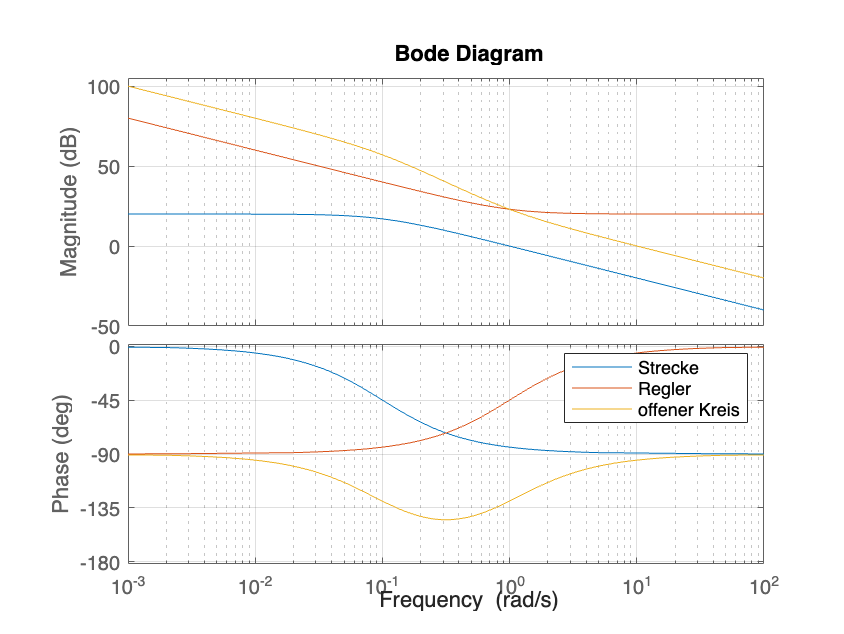

% Offener Kreis
GK0 = K*G0;

% Bode-Diagramme
bode(G0,K,GK0)
grid on
legend('Strecke','Regler','offener Kreis')

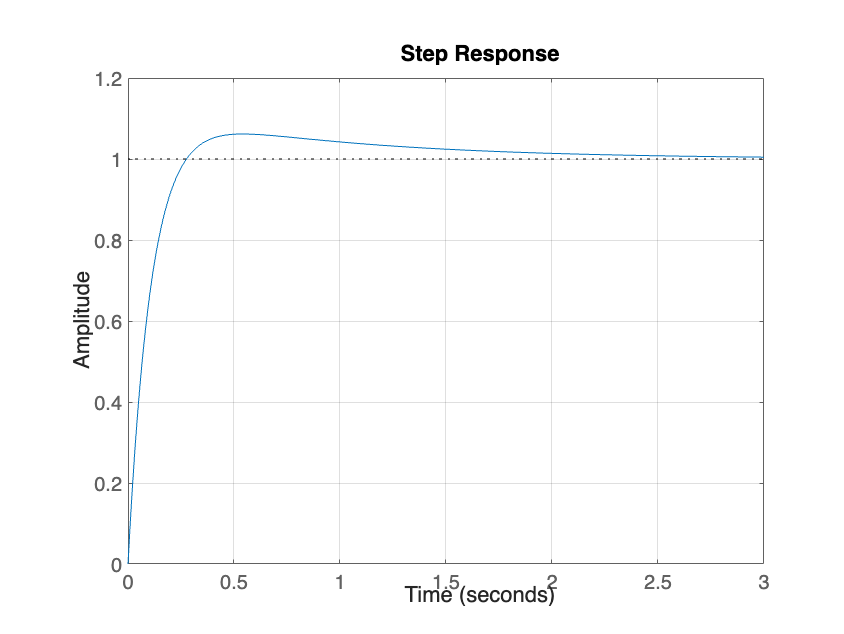


% Geschlossener Kreis
GRK = feedback(GK0,1); %GK0/(1 + GK0);

% Sprungantwort geschlossener Kreis
step(GRK)
grid on